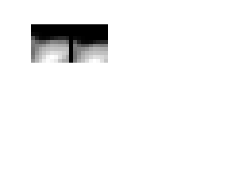

fname = 'atlas0006.nii.gz';
Vatlas = spm_vol(fname);
[Yatlas,XYZ] = spm_read_vols(Vatlas);

fname = 'atlas0006-seg.nii.gz';
Vseg = spm_vol(fname);
[Yseg,XYZ] = spm_read_vols(Vseg);

figure
h = subplot(2,2,1);
imshowpair(Yatlas, Yseg,'montage');
title('Original atlas and seg');

trainingdata = table();  %empty table
trainingdata.tissuetype = reshape(Yseg,[],1);

krn = [
    0 0 0
    0 0 0
    0 0 1
    ];
upperleft_img = convn(Yatlas,krn,'same');

imshowpair(Yatlas(1:10,1:10), upperleft_img(1:10,1:10),'montage');

%all pixels in image Yatlas shifted to the right and down one pixel in
%upperleft_img (opposite corner of kernel).
Yatlas(10,10);
upperleft_img(10,10);



trainingdata = table();  %empty table
trainingdata.uppermid = reshape(Yatlas,[],1);
krn = [
    0 0 0
    0 0 0
    0 1 0
    ];
uppermid_img = convn(Yatlas,krn,'same');
trainingdata.upperright= reshape(Yatlas,[],1);
krn = [
    0 0 0
    0 0 0
    1 0 0
    ];
upperright_img = convn(Yatlas,krn,'same');
trainingdata.right = reshape(Yatlas,[],1);
krn = [
    0 0 0
    1 0 0
    0 0 0
    ];
right_img = convn(Yatlas,krn,'same');
trainingdata.lowerright = reshape(Yatlas,[],1);
krn = [
    1 0 0
    0 0 0
    0 0 0
    ];
lowerright_img = convn(Yatlas,krn,'same');
trainingdata.lowermid = reshape(Yatlas,[],1);
krn = [
    0 1 0
    0 0 0
    0 0 0
    ];
lowermid_img = convn(Yatlas,krn,'same');
trainingdata.lowerleft= reshape(Yatlas,[],1);
krn = [
    0 0 1
    0 0 0
    0 0 0
    ];
lowerleft_img = convn(Yatlas,krn,'same');
trainingdata.left = reshape(Yatlas,[],1);
krn = [
    0 0 0
    0 0 1
    0 0 0
    ];
left_img = convn(Yatlas,krn,'same');
trainingdata.center = reshape(Yatlas,[],1);
krn = [
    0 0 0
    0 1 0
    0 0 0
    ];
center_img = convn(Yatlas,krn,'same');
trainingdata.tissuetype = reshape(Yseg,[],1);
krn = [
    0 0 0
    0 0 0
    0 0 1
    ];
upperleft_img = convn(Yatlas,krn,'same');


knnmodel = fitcknn(trainingdata, 'tissuetype','NumNeighbors', 5);

fname = 'testslice001.nii.gz';
Vtest = spm_vol(fname);
[Ytest,XYZ] = spm_read_vols(Vtest);

testdata=table();
testdata.uppermid = reshape(Ytest,[],1);
krn = [
    0 0 0
    0 0 0
    0 1 0
    ];
uppermid_img = convn(Ytest,krn,'same');
testdata.upperright= reshape(Ytest,[],1);
krn = [
    0 0 0
    0 0 0
    1 0 0
    ];
upperright_img = convn(Ytest,krn,'same');
testdata.right = reshape(Ytest,[],1);
krn = [
    0 0 0
    1 0 0
    0 0 0
    ];
right_img = convn(Ytest,krn,'same');
testdata.lowerright = reshape(Ytest,[],1);
krn = [
    1 0 0
    0 0 0
    0 0 0
    ];
lowerright_img = convn(Ytest,krn,'same');
testdata.lowermid = reshape(Ytest,[],1);
krn = [
    0 1 0
    0 0 0
    0 0 0
    ];
lowermid_img = convn(Ytest,krn,'same');
testdata.lowerleft= reshape(Ytest,[],1);
krn = [
    0 0 1
    0 0 0
    0 0 0
    ];
lowerleft_img = convn(Ytest,krn,'same');
testdata.left = reshape(Ytest,[],1);
krn = [
    0 0 0
    0 0 1
    0 0 0
    ];
left_img = convn(Ytest,krn,'same');
testdata.center = reshape(Ytest,[],1);
krn = [
    0 0 0
    0 1 0
    0 0 0
    ];
center_img = convn(Ytest,krn,'same');

test_tissuetype = predict(knnmodel,testdata);
Ytest_seg = reshape(test_tissuetype,size(Ytest));

figure

subplot(1,3,1)
imshow(Ytest)
title('Test slice')

subplot(1,3,2)
imshow(Ytest_seg,[])
title('Registered segmentation')

subplot(1,3,3)
imshow(labeloverlay(Ytest,Ytest_seg,'Transparency',0.7))
title('Both combined')
%when overlaid, little difference is observed between images


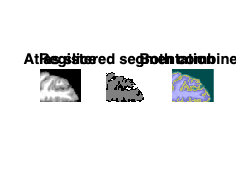

fname = 'atlas0011.nii.gz';
Vatlas1 = spm_vol(fname);
[Yatlas1,XYZ] = spm_read_vols(Vatlas1);

atlasdata=table();
atlasdata.uppermid = reshape(Yatlas1,[],1);
krn = [
    0 0 0
    0 0 0
    0 1 0
    ];
uppermid_img = convn(Yatlas1,krn,'same');
atlasdata.upperright= reshape(Yatlas1,[],1);
krn = [
    0 0 0
    0 0 0
    1 0 0
    ];
upperright_img = convn(Yatlas1,krn,'same');
atlasdata.right = reshape(Yatlas1,[],1);
krn = [
    0 0 0
    1 0 0
    0 0 0
    ];
right_img = convn(Yatlas1,krn,'same');
atlasdata.lowerright = reshape(Yatlas1,[],1);
krn = [
    1 0 0
    0 0 0
    0 0 0
    ];
lowerright_img = convn(Yatlas1,krn,'same');
atlasdata.lowermid = reshape(Yatlas1,[],1);
krn = [
    0 1 0
    0 0 0
    0 0 0
    ];
lowermid_img = convn(Yatlas1,krn,'same');
atlasdata.lowerleft= reshape(Yatlas1,[],1);
krn = [
    0 0 1
    0 0 0
    0 0 0
    ];
lowerleft_img = convn(Yatlas1,krn,'same');
atlasdata.left = reshape(Yatlas1,[],1);
krn = [
    0 0 0
    0 0 1
    0 0 0
    ];
left_img = convn(Yatlas1,krn,'same');
atlasdata.center = reshape(Yatlas1,[],1);
krn = [
    0 0 0
    0 1 0
    0 0 0
    ];
center_img = convn(Yatlas1,krn,'same');

atlas_tissuetype = predict(knnmodel,atlasdata);
Yatlas_seg = reshape(atlas_tissuetype,size(Yatlas1));

figure

subplot(1,3,1)
imshow(Yatlas)
title('Atlas slice')

subplot(1,3,2)
imshow(Yatlas_seg,[])
title('Registered segmentation')

subplot(1,3,3)
imshow(labeloverlay(Yatlas,Yatlas_seg,'Transparency',0.7))
title('Both combined')

%loverlay matches well between atlas and segmentation

%atlas 006 appears to be a more blurred anatomical image with a wider variety of voxel values whereas the
%process used for atlas 0011 separated voxels into catagories and assigned
%a value using training data to predict/assign voxel values to different tissue
%types.


pixelfeatures = table2array(testdata(184,:))

pixelfeatures =     0.8613    0.8613    0.8613    0.8613    0.8613    0.8613    0.8613    0.8613


trainfeatures = table2array(trainingdata(:,2:end));
squared_distances = sum((pixelfeatures - trainfeatures).^2,2);
[~,indices] = sort(squared_distances);
neighbor_indices = indices(1:5);
showdata = trainingdata;
showdata.distance = sqrt(squared_distances);
showdata(neighbor_indices,:)

ans = 5×10 table
    uppermid    upperright    right     lowerright    lowermid    lowerleft     left     center    tissuetype    distance
    ________    __________    ______    __________    ________    _________    ______    ______    __________    ________

     0.6626       0.6626      0.6626      0.6626       0.6626      0.6626      0.6626    0.6626        1          0.5437 
     0.6625       0.6625      0.6625      0.6625       0.6625      0.6625      0.6625    0.6625        1         0.54396 
     0.6624       0.6624      0.6624      0.6624       0.6624      0.6624      0.6624    0.6624        1         0.54421 
     0.6623       0.6623      0.